# Підготовка

clear; close all; clc;

I1 = imread('spine.tif');
I2 = imread('wagon.jpg');

## 1-2. Відображення вихідних зображень

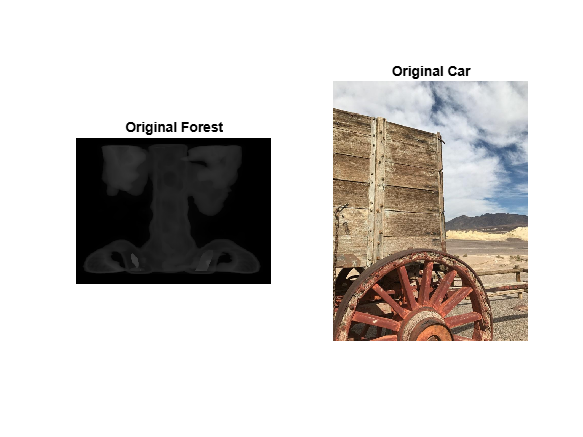

figure('Name','Original Images');
subplot(1,2,1), imshow(I1), title('Original Spine');
subplot(1,2,2), imshow(I2), title('Original Wagon');

## 3-4. Зашумлення зображення нормальним білим шумом та імпульсною перешкодою з різною щільністю

Gaussian: середнє=0, дисперсія=0.01 (для spine), 0.05 (для wagon). 

Salt & pepper: ймовірність шуму 0.02 (для spine), 0.05 (для wagon).

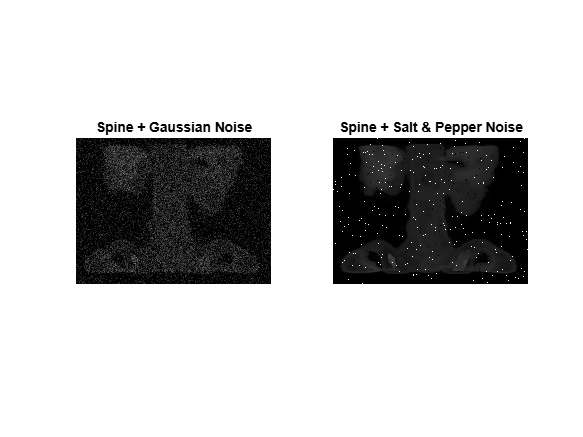

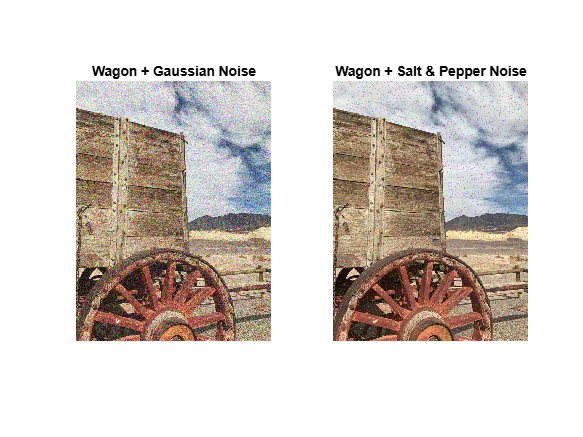

I1_gauss = imnoise(I1, 'gaussian', 0, 0.01);
I1_sp    = imnoise(I1, 'salt & pepper', 0.02);
I2_gauss = imnoise(I2, 'gaussian', 0, 0.05);
I2_sp    = imnoise(I2, 'salt & pepper', 0.05);

figure('Name','Noisy Images - Spine');
subplot(1,2,1), imshow(I1_gauss), title('Spine + Gaussian Noise');
subplot(1,2,2), imshow(I1_sp),    title('Spine + Salt & Pepper Noise');

figure('Name','Noisy Images - Wagon');
subplot(1,2,1), imshow(I2_gauss), title('Wagon + Gaussian Noise');
subplot(1,2,2), imshow(I2_sp),    title('Wagon + Salt & Pepper Noise');

% Gaussian noise (нормальний білий шум) розподіляється за гаусівською кривою.
% Salt & pepper (імпульсний шум) випадково задає яскраво-білі та чорні точки.

## 5-6. Фільтрація зашумлених зображень лінійними фільтрами

Усереднювальний (average): низькочастотний 

Гаусівський (gaussian): також низькочастотний, але з гаусівською вагою

Unsharp: фільтр підвищення різкості (фактично високочастотний)

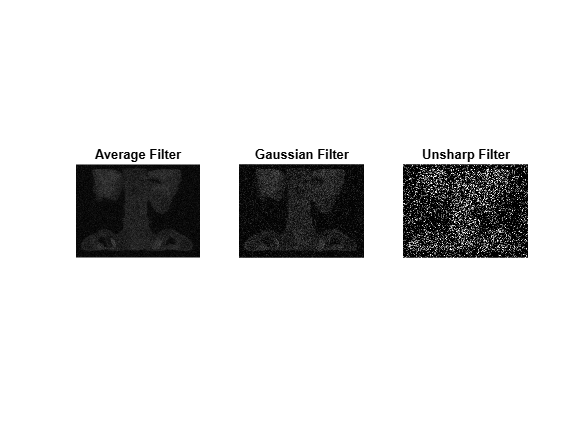

h_avg    = fspecial('average', [3 3]);      % 3x3 усереднювальний фільтр
h_gauss  = fspecial('gaussian', [3 3], 0.5);% 3x3 гаусівський фільтр, sigma=0.5
h_unsharp= fspecial('unsharp');             % фільтр для підсилення різкості

% --- Spine ---
% Gaussian noise
cam_gauss_avg    = imfilter(I1_gauss, h_avg);
cam_gauss_gauss  = imfilter(I1_gauss, h_gauss);
cam_gauss_unsharp= imfilter(I1_gauss, h_unsharp);

% Salt & Pepper noise
cam_sp_avg       = imfilter(I1_sp, h_avg);
cam_sp_gauss     = imfilter(I1_sp, h_gauss);
cam_sp_unsharp   = imfilter(I1_sp, h_unsharp);

% --- Wagon ---
% Gaussian noise
pep_gauss_avg    = imfilter(I2_gauss, h_avg);
pep_gauss_gauss  = imfilter(I2_gauss, h_gauss);
pep_gauss_unsharp= imfilter(I2_gauss, h_unsharp);

% Salt & Pepper noise
pep_sp_avg       = imfilter(I2_sp, h_avg);
pep_sp_gauss     = imfilter(I2_sp, h_gauss);
pep_sp_unsharp   = imfilter(I2_sp, h_unsharp);

figure('Name','Spine Gaussian Noise - Linear Filters');
subplot(1,3,1), imshow(cam_gauss_avg),     title('Average Filter');
subplot(1,3,2), imshow(cam_gauss_gauss),   title('Gaussian Filter');
subplot(1,3,3), imshow(cam_gauss_unsharp), title('Unsharp Filter');

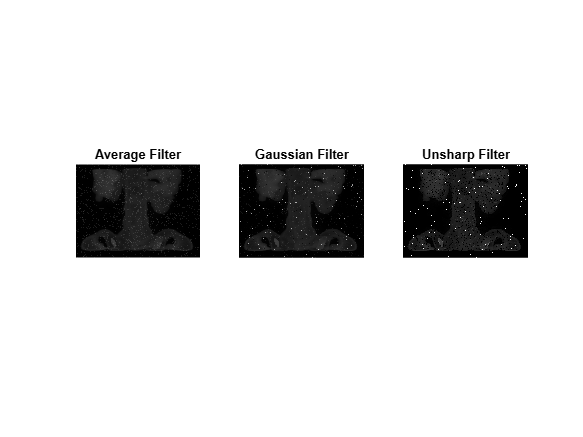


figure('Name','Spine Salt & Pepper Noise - Linear Filters');
subplot(1,3,1), imshow(cam_sp_avg),     title('Average Filter');
subplot(1,3,2), imshow(cam_sp_gauss),   title('Gaussian Filter');
subplot(1,3,3), imshow(cam_sp_unsharp), title('Unsharp Filter');

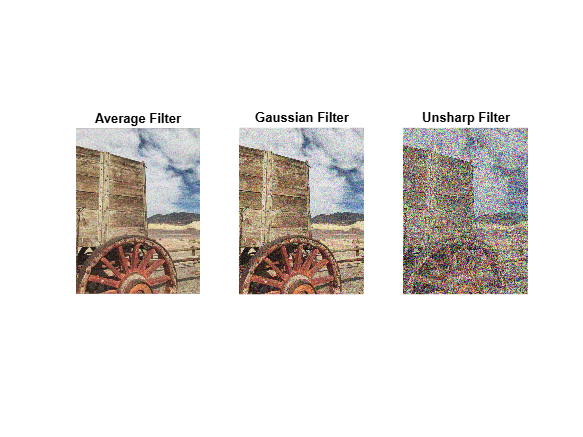


figure('Name','Wagon Gaussian Noise - Linear Filters');
subplot(1,3,1), imshow(pep_gauss_avg),     title('Average Filter');
subplot(1,3,2), imshow(pep_gauss_gauss),   title('Gaussian Filter');
subplot(1,3,3), imshow(pep_gauss_unsharp), title('Unsharp Filter');

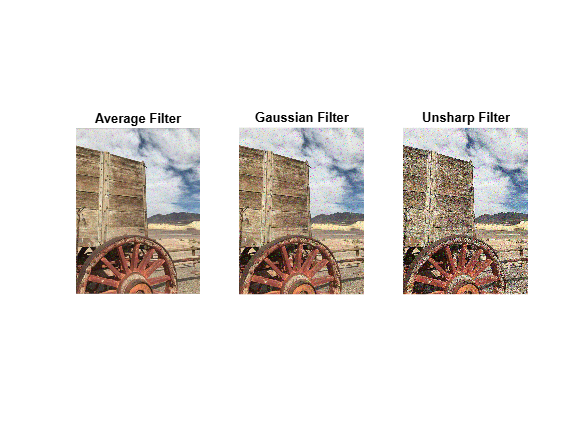


figure('Name','Wagon Salt & Pepper Noise - Linear Filters');
subplot(1,3,1), imshow(pep_sp_avg),     title('Average Filter');
subplot(1,3,2), imshow(pep_sp_gauss),   title('Gaussian Filter');
subplot(1,3,3), imshow(pep_sp_unsharp), title('Unsharp Filter');


% Фільтри низьких частот (average, gaussian) розмивають різкі переходи, пригнічують шум, але зменшують різкість.
% Фільтр Unsharp підсилює різкі переходи (краї), що підвищує чіткість.

## 7. Адаптивна фільтрація wiener2

Wiener2 адаптивно підлаштовується до локальної дисперсії зображення. Для сірого зображення можна застосувати напряму, а для кольорового по каналах.

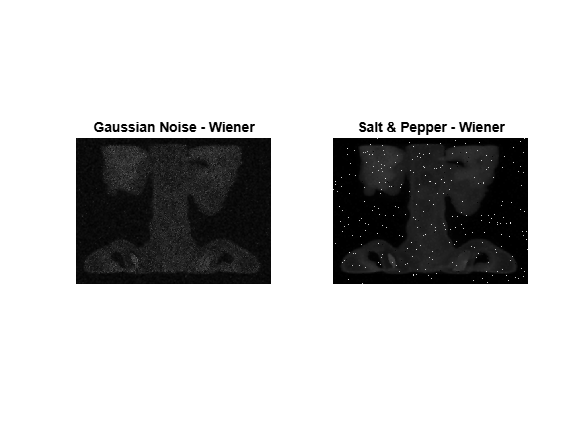

% --- Spine ---
cam_gauss_wiener = wiener2(I1_gauss, [5 5]);
cam_sp_wiener    = wiener2(I1_sp,    [5 5]);

figure('Name','Cameraman - Wiener Filter');
subplot(1,2,1), imshow(cam_gauss_wiener), title('Gaussian Noise - Wiener');
subplot(1,2,2), imshow(cam_sp_wiener),    title('Salt & Pepper - Wiener');

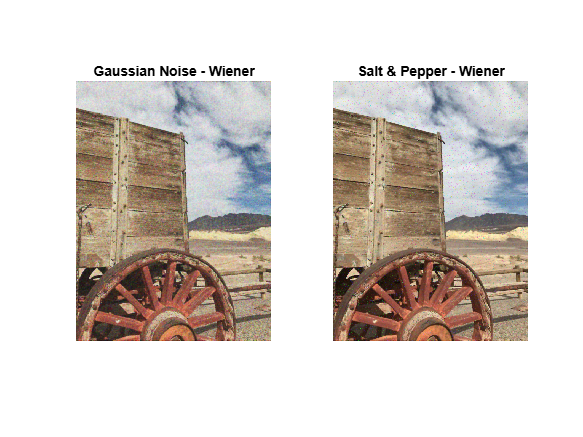


% --- Wagon ---
% Розділяємо на канали
pr_gauss = I2_gauss(:,:,1); pg_gauss = I2_gauss(:,:,2); pb_gauss = I2_gauss(:,:,3);
pr_sp    = I2_sp(:,:,1);    pg_sp    = I2_sp(:,:,2);    pb_sp    = I2_sp(:,:,3);

% Фільтруємо кожен канал
pr_gauss_w = wiener2(pr_gauss,[5 5]);
pg_gauss_w = wiener2(pg_gauss,[5 5]);
pb_gauss_w = wiener2(pb_gauss,[5 5]);
pr_sp_w    = wiener2(pr_sp,[5 5]);
pg_sp_w    = wiener2(pg_sp,[5 5]);
pb_sp_w    = wiener2(pb_sp,[5 5]);

% Об'єднуємо назад
pep_gauss_wiener = cat(3, pr_gauss_w, pg_gauss_w, pb_gauss_w);
pep_sp_wiener    = cat(3, pr_sp_w,    pg_sp_w,    pb_sp_w);

figure('Name','Peppers - Wiener Filter');
subplot(1,2,1), imshow(pep_gauss_wiener), title('Gaussian Noise - Wiener');
subplot(1,2,2), imshow(pep_sp_wiener),    title('Salt & Pepper - Wiener');


% Wiener2 оцінює локальні статистики (середнє, дисперсію) та зменшує шум
% ефективніше, ніж фіксований лінійний фільтр, особливо при нестаціонарних шумах.

## 8-9. Медіанна фільтрація

Медіанна фільтрація добре пригнічує імпульсні шуми, зберігаючи краї краще, ніж середнє згладжування.

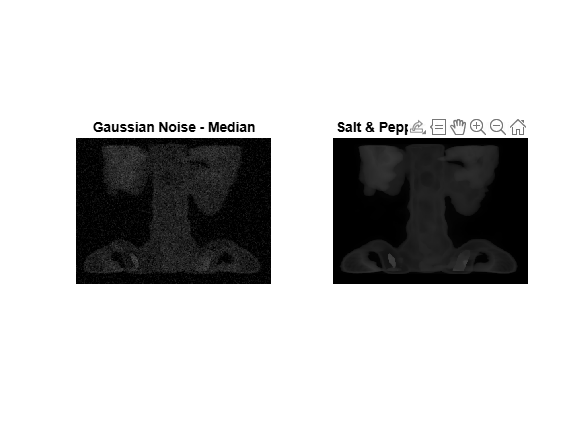

% --- Spine ---
cam_gauss_med = medfilt2(I1_gauss, [3 3]);
cam_sp_med    = medfilt2(I1_sp,    [3 3]);

figure('Name','Cameraman - Median Filter');
subplot(1,2,1), imshow(cam_gauss_med), title('Gaussian Noise - Median');
subplot(1,2,2), imshow(cam_sp_med),    title('Salt & Pepper Noise - Median');

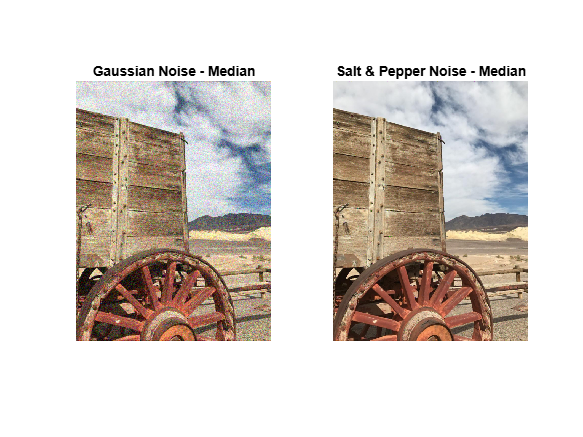


% --- Wagon ---
% Медіанний фільтр до кожного каналу
pr_gauss_med = medfilt2(pr_gauss, [3 3]);
pg_gauss_med = medfilt2(pg_gauss, [3 3]);
pb_gauss_med = medfilt2(pb_gauss, [3 3]);
pep_gauss_med = cat(3, pr_gauss_med, pg_gauss_med, pb_gauss_med);

pr_sp_med = medfilt2(pr_sp, [3 3]);
pg_sp_med = medfilt2(pg_sp, [3 3]);
pb_sp_med = medfilt2(pb_sp, [3 3]);
pep_sp_med = cat(3, pr_sp_med, pg_sp_med, pb_sp_med);

figure('Name','Peppers - Median Filter');
subplot(1,2,1), imshow(pep_gauss_med), title('Gaussian Noise - Median');
subplot(1,2,2), imshow(pep_sp_med),    title('Salt & Pepper Noise - Median');

 При імпульсному шумі ("сіль і перець") медіанний фільтр особливо ефективний, оскільки відкидає аномальні "сплески" (білі/чорні точки) без надмірного розмивання решти зображення. 

Gaussian Noise: Добре працюють лінійні низькочастотні фільтри (average, gaussian), а також адаптивний Wiener. 

Salt & Pepper Noise (імпульсний): Найкраще підходить медіанний фільтр, хоча Wiener теж може давати прийнятний результат.

Лінійні фільтри згладжують шуми, але при імпульсному шумі вони розмивають яскраві точки й можуть псувати контрасти.

Медіанний фільтр для імпульсних шумів працює краще, бо вибирає середнє значення серед сусідів, ігноруючи аномальні піки. 

Wiener2 адаптивно враховує локальну варіацію, тому може бути компромісом і для гаусівського, і для імпульсного шуму.

## 10. Відповіді на запитання

**1. Поясніть процедуру лінійної фільтрації зображення віконним фільтром**

Суть лінійної (віконної) фільтрації полягає в тому, що для кожного пікселя вхідного зображення обчислюється нове значення як лінійна комбінація (зважене середнє) сусідніх пікселів у деякому "вікні". Вибір ядра (вікна), це матриця коефіцієнтів (наприклад, `3 на 3`, `5 на 5` тощо). Для кожного пікселя в центрі цього вікна береться сума добутків яскравості сусідніх пікселів на відповідні коефіцієнти ядра. Результат записується у вихідне зображення в позиції цього пікселя. Якщо сума коефіцієнтів дорівнює 1, це називають фільтром згортки, який зберігає загальну яскравість зображення, але змінює розподіл деталей (шуму, контурів).

**2. Чому відрізняються «вікна фільтрів» для низькочастотної і високочастотної фільтрації?**

Низькочастотні фільтри (наприклад, усереднювальний чи гаусівський) мають коефіцієнти, що всі невід’ємні та (зазвичай) сумуються в 1. Вони згладжують (усереднюють) яскравості, зменшують шум, але можуть розмивати краї.

Високочастотні фільтри (наприклад, фільтр підсилення різкості, unsharp) містять як додатні, так і від’ємні коефіцієнти, які підкреслюють або підсилюють перепади яскравості (краї). Такі ядра можуть мати суму коефіцієнтів, що дорівнює 0 або близько 0, щоб віднімати низькочастотну складову і залишати лише деталі.

**3. Як змінюється вигляд зображення після його фільтрації низькочастотними фільтрами?**

Основна зміна - зображення стає гладкішим, дрібні деталі та шум приглушуються.

Побічний зміна - краї стають менш чіткими, відбувається розмиття.

**4. Як змінюється вигляд зображення після його фільтрації високочастотними фільтрами?**

Основна зміна - краї та дрібні деталі підкреслюються або посилюються, зображення може виглядати різкішим.

Побічний зміна - водночас може підсилюватися й шум, бо шум це також високочастотна компонента.

**5. Для перешкод якого характеру більше підходить медіанна фільтрація і чому?**

Медіанна фільтрація найкраще справляється з імпульсними шумами (наприклад, "сіль і перець"), оскільки медіанний фільтр замість простого усереднення бере медіану з пікселів у вікні. Це дає змогу "відкинути" поодинокі аномально яскраві чи темні пікселі (що є типовим для імпульсного шуму) без сильного розмиття країв. Таким чином, при імпульсному шумі медіанний фільтр зазвичай ефективніший за лінійні фільтри, які розмазують поодинокі "сплески" шуму по всьому вікну.